# OGLO notebook 7

HNXJ@github

Spectrolamniar V2.0

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
addpath(genpath('flipv2'));
generateCore();

addpath('fieldtrip');ft_defaults;
nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


nwbFile = nwbPath + nwbFiles{3};
nwb = nwbRead(nwbFile);
disp(nwbFile);

data\sub-C31o_ses-230818.nwb


[pinfo, xa] = jNWBSignals(nwb, 0, "flash", 500, 500, "lfp");


>flash:
->Total correct trials: 100

-->Total blocks: 1

-->Total conditions: 1

--->Condition 1 : 100 trials, 100 correct 

->Total trials: 100

Area(s): PFC
_


[pinfo, xb] = jNWBSignals(nwb, 2, "flash", 500, 500, "lfp");


>flash:
->Total correct trials: 100

-->Total blocks: 1

-->Total conditions: 1

--->Condition 1 : 100 trials, 100 correct 

->Total trials: 100

Area(s): MT, MST
_


[pinfo, ma] = jNWBSignals(nwb, 0, "flash", 500, 500, "muae");


>flash:
->Total correct trials: 100

-->Total blocks: 1

-->Total conditions: 1

--->Condition 1 : 100 trials, 100 correct 

->Total trials: 100

Area(s): PFC
_


[pinfo, mb] = jNWBSignals(nwb, 2, "flash", 500, 500, "muae");


>flash:
->Total correct trials: 100

-->Total blocks: 1

-->Total conditions: 1

--->Condition 1 : 100 trials, 100 correct 

->Total trials: 100

Area(s): MT, MST
_


data = xa{1};
data = permute(data, [2, 3, 1]);
imx1 = squeeze(mean(data, 3));

lastg = 1;
nextg = 0;

% for ik = 1:128
% 
%     nextg = 0;
% 
%     for jk = lastg+1:128
% 
%         psp = pspectrum(imx1(jk, :));
% 
%         if cindex > -25  && ~nextg
% 
%             nextg = jk;
% 
%         end
% 
%     end
% 
%     if ~nextg
% 
%         nextg = lastg;
% 
%     end
% 
%     cindex = 100*(chx(ik) - chx(lastg))/chx(nextg);
% 
%     if cindex < -30
% 
%         data(ik, :, :) = (data(lastg, :, :) + data(nextg, :, :))/2;
% 
%     else
% 
%         lastg = ik;
% 
%     end
% 
% end

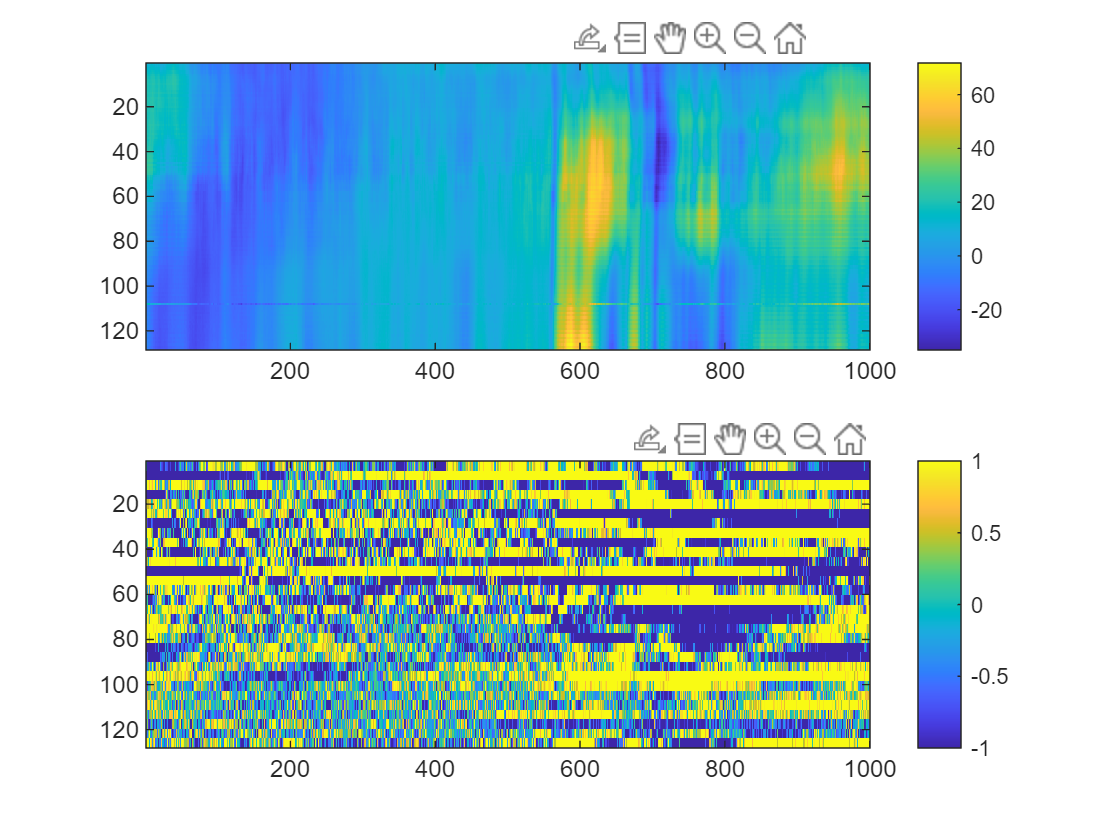

data = xb{1};
data = permute(data, [2, 3, 1]);
% imx1 = squeeze(mean(data, 3));

spacing = 4;chmp = 1:128;
imx1 = squeeze(mean(data(chmp, :, :), 3));

for ik = chmp
    imx1(ik, :) = (imx1(ik, :) - mean(imx1(ik, 1:500))) / (std(imx1(ik, 1:500))/sqrt(100));
end

% imx1 = jMeanFilt2(imx1, 3, 10);
figure;
subplot(2, 1, 1);imagesc(imx1);colorbar;
csdimx1 = imx1(1:spacing:end-spacing*2, :) - 2*imx1(1+spacing:spacing:end-spacing, :) + imx1(1+spacing*2:spacing:end, :);
ym = linspace(min(chmp)+2, max(chmp)-2, size(csdimx1, 1));
subplot(2, 1, 2);imagesc(csdimx1, "YData", ym);colorbar;clim([-1 1])

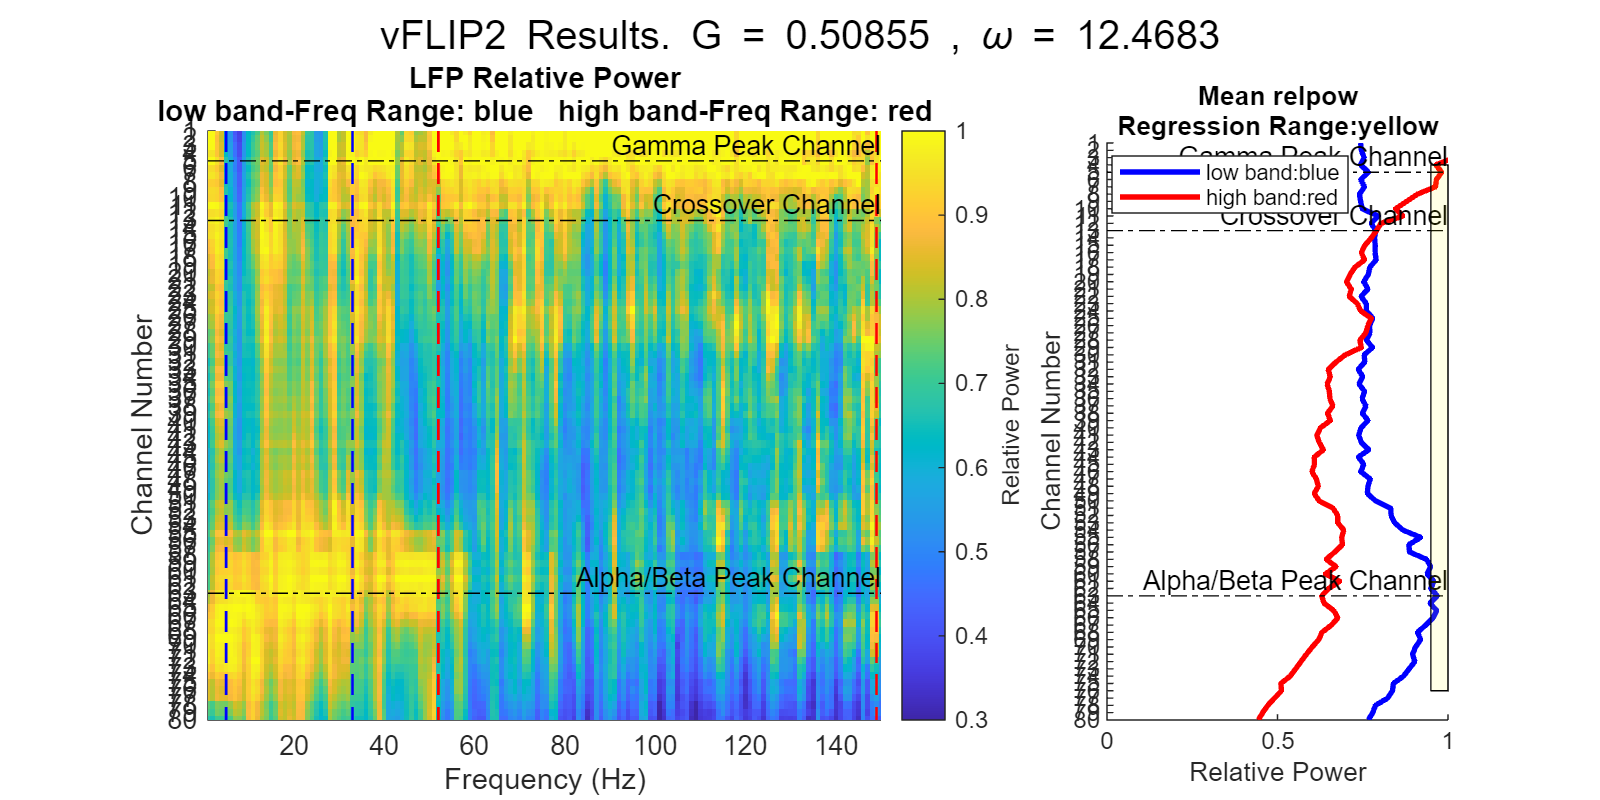

flipObj = vFLIP2(data(chmp, :, :), 'DataType', 'raw_cut', 'fsample', 1000, 'intdist', 0.04, 'plot_result', true);

results = flipObj.Results;

flipObj = vFLIP2(data, 'DataType', 'raw_cut', 'fsample', 1000, 'intdist', 0.025, 'plot_result', true);
results = flipObj.Results;